Unsharpining an image

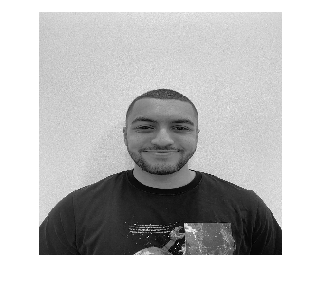

[me,melut] = imread("megray.tif"); % original image
imshow(me);

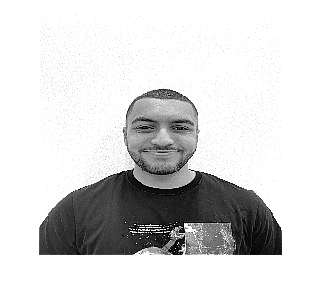


filter = fspecial("average",3);% blurring filter
filtered_me = filter2(filter,me); %blurred image
filtered_me_scaled = filtered_me*0.5;%scaling the image by multiplying it by a factor x<1
subtracted_image = double(me) - filtered_me_scaled; % subtract the scaled image from your original image
%joint = [me subtracted_image];
%imshow(joint);
imshow(subtracted_image/100);

pelicans image

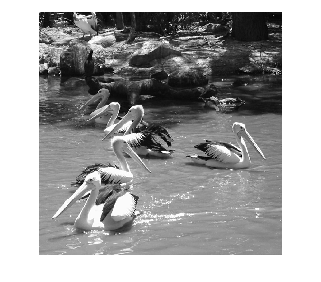

[me,melut] = imread("pelicans.tif"); % original image
imshow(me);

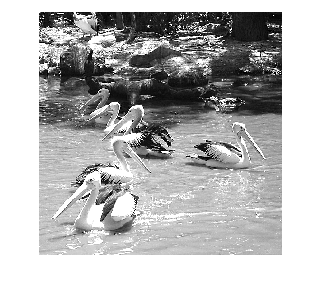


filter = fspecial("average",3);% blurring filter
filtered_me = filter2(filter,me); %blurred image
filtered_me_scaled = filtered_me*0.5;%scaling the image by multiplying it by a factor x<1
subtracted_image = double(me) - filtered_me_scaled; % subtract the scaled image from your original image
%joint = [me subtracted_image];
%imshow(joint);
imshow(subtracted_image/100);

Using unsharp with fspecial

[me,melut] = imread("pelicans.tif"); % original image
imshow(me);

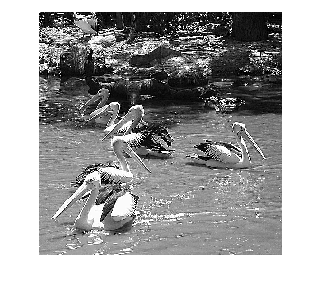


filter = fspecial("unsharp",0.5);% blurring filter
filtered_me = filter2(filter,me); %blurred image

imshow(filtered_me/255);

Non linear functions

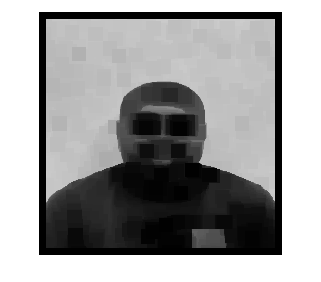

cam = imread("cameraman.tif");
% cmax = nlfilter(cam,[3,3],'max(x(:))');
% imshow(cmax);
% 
% cmin = nlfilter(cam,[3,3],'min(x(:))');
% imshow(cmin);


% memax = nlfilter(me,[5,5],'max(x(:))');
% imshow(memax);

memin = nlfilter(me,[15,15],'min(x(:))');
imshow(memin);